## Ejercicio 1 y 2 


$$\mathrm{Fs}={8000}_{\frac{\mathrm{samples}}{\sec }}$$


SAMPLES_SECOND = 8000;

## Ruido Aditivo Gaussiano 

En cualquier corriente electrica hay un flujo de electrones atravez de un conductor. Sin embargo la conduccion es caotica y los electronces cambian de un atomo otro de forma caotica generando variacioness en la medicion de las señales. Dado que estos cambios son en pequeños instantes de tiempo se dice que son de energia finita. 

El teorema del **limite central** menciona que la suma de multiples distribuciones de energia fintia se asemeja a una distribucion gaussiana. 


$$\frac{1}{\sigma \sqrt{2\pi }}e^{{-\frac{x}{2}}^2 }$$


Entre mas variaciones existan en esta distribucion quiere decir que hay mas energia, por lo tanto la potencia promedio de la señal esta dada por

 
$$\sigma =P_{\mathrm{avg}}$$



$$\mathrm{randn}=f\left(x\right)=\frac{1}{\sqrt{2\pi }}e^{{-\frac{x}{2}}^2 }$$


Y se le agrega la component $\sigma$


$$\mathrm{randn}=f\left(x\right)=\frac{1}{W_{\mathrm{noise}} \sqrt{2\pi }}e^{{-\frac{x}{2}}^2 }$$


A este rudio se el conoce como **AWGN**

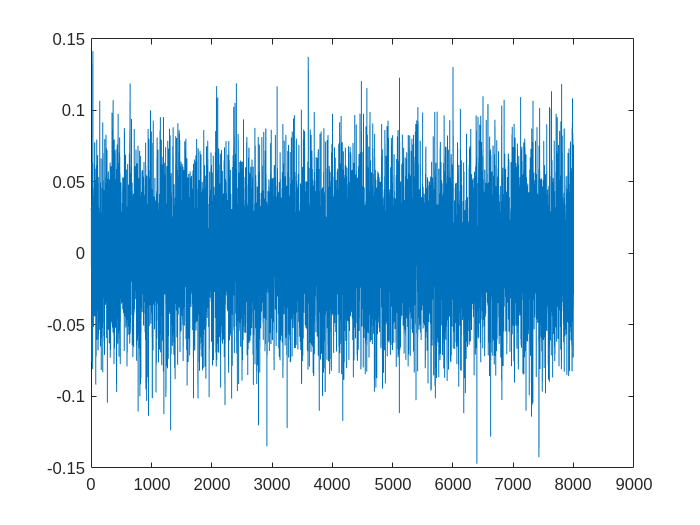

sigma = .0014; %watts
gausian_noise = sqrt(sigma)*randn(1,SAMPLES_SECOND+1);
gausian_noise = gausian_noise'; % make compatible with sound colum vector to row vector
plot(gausian_noise)

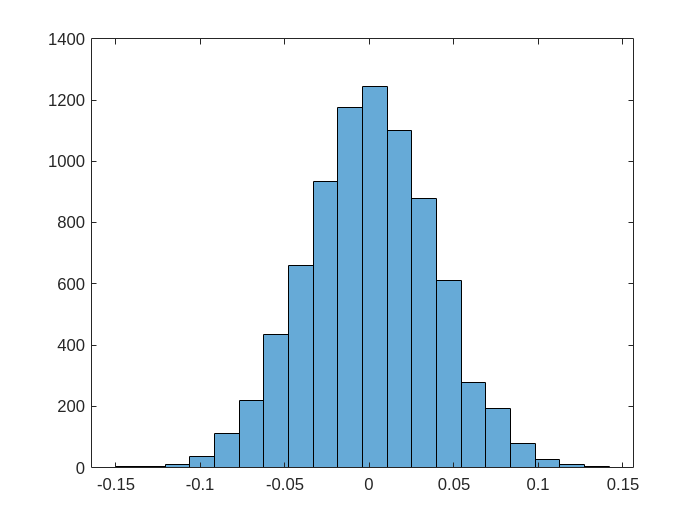

histogram(gausian_noise,20); % distribucion gaussiana del ruido 

La potencia del ruido es muy cercana a la varianza. En teoria son iguales. 

pow_noise =  gausian_noise'*gausian_noise / length(gausian_noise)

pow_noise = 0.0014

sigma

sigma = 0.0014

## LECTURA DE AUDIO DE VOZ

- 8,000 Muestras por segundo

- monoaural

- PCM 8 Bits por muestras

[y, Fs] = audioread("Audios/grape-juice.wav");

El siguiente codigo se colo para garantizar el sample rate en caso de que este en otro. 

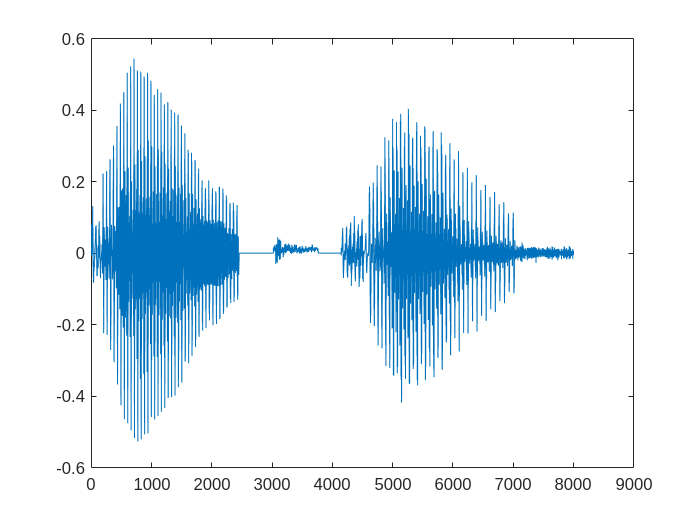

s_down_resample = resample(y, SAMPLES_SECOND, Fs);
m_t = s_down_resample(1:(SAMPLES_SECOND+1)); %cut one second final message signal
plot(m_t);

## SNR

El SNR es la relacion de potencia entre la señal de interes y el ruido. 

Para que la Voz sea Inteligible, la SNR debe de estar entre 5db a 10db.  Dicho esto procedmos a tomar la potencia de la señal.

pow_voice =  m_t'*m_t  / length(m_t)

pow_voice = 0.0100

 Ajustaremos el ruido al minimo inteligible con 5db.


$$\mathrm{SNR}=10*\log_{10} \;\left(\frac{P_{\mathrm{SIG}} }{p_{\mathrm{NOISE}} }\right)$$



$$5\mathrm{db}=10*\log_{10} \;\left(\frac{P_{\mathrm{SIG}} }{p_{\mathrm{NOISE}} }\right)$$



$${10}^{\frac{\left(5\mathrm{db}\right)}{10}} =\left(\frac{P_{\mathrm{SIG}} }{p_{\mathrm{NOISE}} }\right)$$



$$p_{\mathrm{NOISE}}$$

$$=\left(\frac{P_{\mathrm{SIG}} }{{10}^{\frac{\left(5\mathrm{db}\right)}{10}} }\right)$$



$$p_{\textrm{NOISE}}$$

$$=\left(\frac{P_{\mathrm{SIG}} }{{10}^{\ldotp 5} }\right)$$



$$p_{\textrm{NOISE}}$$

$$=\left(\frac{P_{\mathrm{SIG}} }{\sqrt{10}}\right)$$


Ajustamos la señal de ruido. 

%recreadno ruido
sigma = pow_voice/sqrt(10); %watts
gausian_noise = sqrt(sigma)*randn(1,SAMPLES_SECOND+1);
gausian_noise = gausian_noise'; 

Calculamos el SNR 


$$\mathrm{SNR}=10*\log_{10} \;\left(\frac{P_{\mathrm{SIG}} }{p_{\mathrm{NOISE}} }\right)$$


snr_signal = pow_voice / sigma;
db_signal_snr = 10*log10(snr_signal)

db_signal_snr = 5

Reproducimos la señal de audio con su minimo inteligible

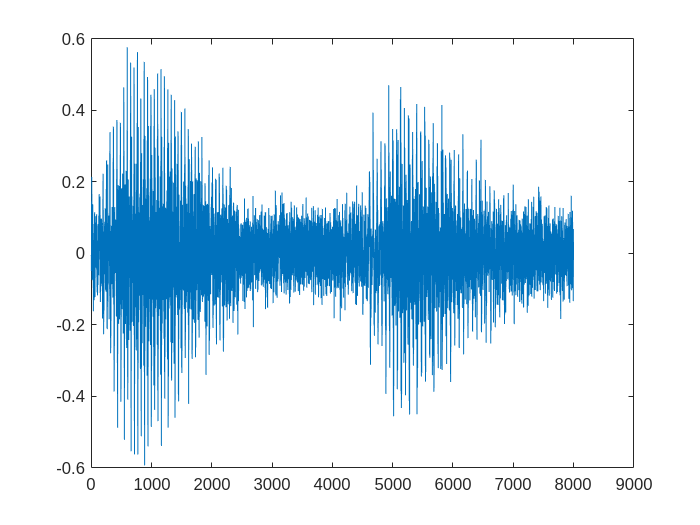

noisesound = gausian_noise + m_t;
plot(noisesound)

%sound(noisesound,SAMPLES_SECOND);

## SIR

La señal interferencia suele ser mas estricta ya que la potencia puede estar especialemente en las frecuencias de interes.Es una medida comparativa entre la potencia de señal y la potencia de las interferencias o del ruido, son utiles solo si el BER es una funcion monotonica, SIR puede llegar a tener valores menores de 1db, lo que hace que predominen las interferencias. 

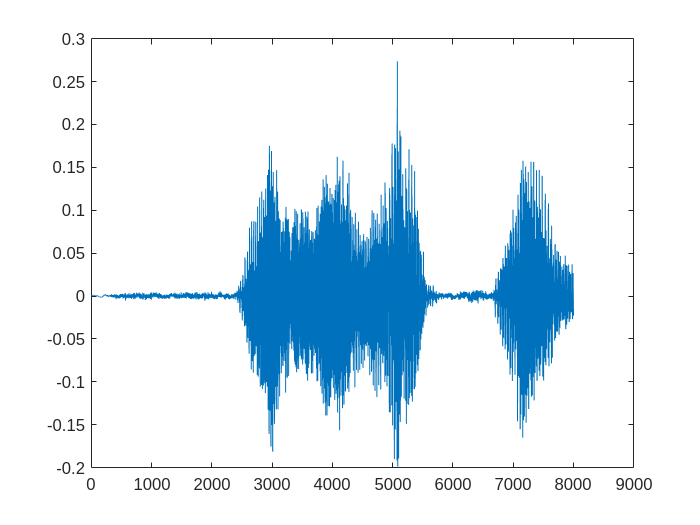

[y, Fs] = audioread("Audios/seriously.wav");
y= y(:,1); % Read one chann
s_down_resample = resample(y, SAMPLES_SECOND, Fs);
interf = s_down_resample(1:(SAMPLES_SECOND+1)); %cut one second final message signal
plot(interf);

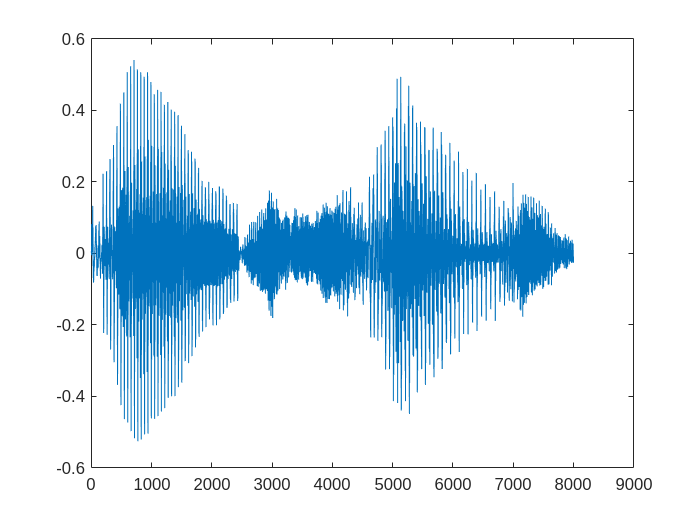

sum_signals = interf + m_t;
plot(sum_signals);

sound(sum_signals,SAMPLES_SECOND);


$$\mathrm{SIR}=\frac{P_{\mathrm{sig}} }{P_{\mathrm{interf}} }$$


pow_interference =  interf'*interf  / length(interf)

pow_interference = 0.0016

pow_voice

pow_voice = 0.0100

rsi_signal = pow_voice /pow_interference;
db_signal_rsi = 10*log10(rsi_signal)

db_signal_rsi = 7.8240